**Beta**

smoothed = smooth3(-mat, 'box', [3 5 3]);
minA = -0.985;
maxA = - 0.97;
border = 410;
timeSize = size(mat,3);

for i=1:size(smoothed,1)
    for j=1:size(smoothed,2)
        for k=1:size(smoothed,3)
            current = smoothed(i,j,k);

            if(current > maxA)
                if (j > border)
                    result = 0.5;
                else
                    result = 1;
                end
            
            elseif (current < minA)
                result = 0;
            else
                result = (current - minA)/(maxA - minA);
            end

            smoothed(i,j,k) = result;
        end
    end
end

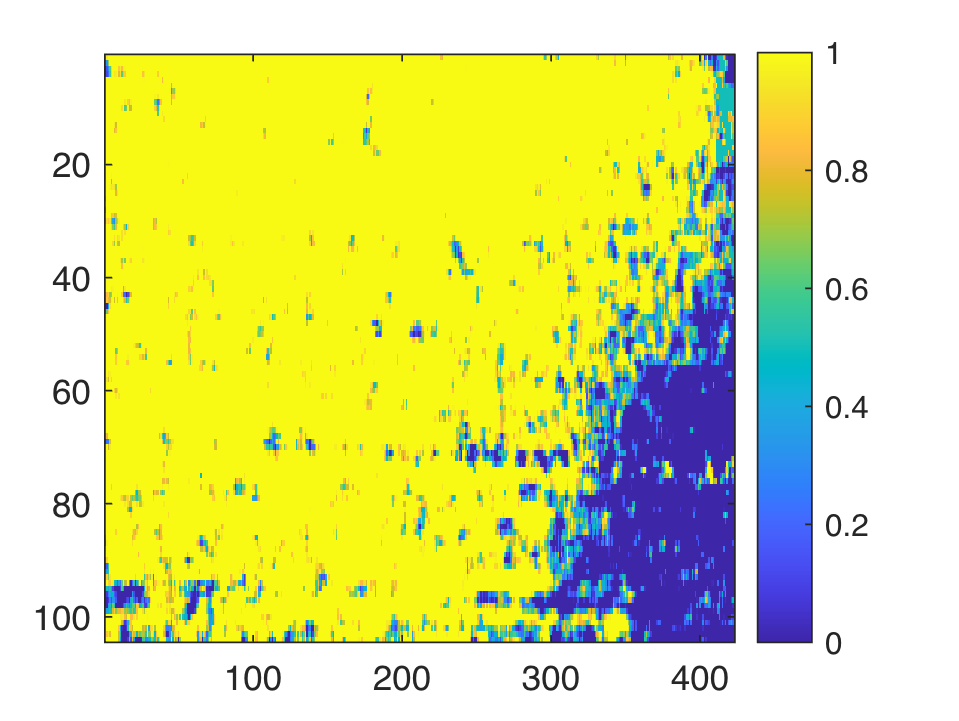


t =119;
current = smoothed(:,:,t);
imagesc(current);
caxis([0 1]);
colorbar;



Area = zeros(size(smoothed,3),1);
Perimeter = zeros(size(smoothed,3),1);
Velocity = zeros(size(smoothed,3),1);

for t=1:size(smoothed,3)
    currentMat = smoothed(:,:,t);
    Area(t) = sum(currentMat,'all');

    currentPerimeter = 0;
    for i=1:size(currentMat,1)
        for j=1:size(currentMat,2)
            currentPixel = currentMat(i,j);
            currentPerimeter = currentPerimeter + 0.5 - abs(currentPixel - 0.5);
        end
    end

    Perimeter(t) = currentPerimeter;
end

VirtualLength = Area ./ Perimeter;
smoothedVirtualLength = smoothdata(VirtualLength);
for i=2:size(smoothedVirtualLength)
    Velocity(i) = smoothedVirtualLength(i) - smoothedVirtualLength(i-1);
end

Beta = (Perimeter .^2) ./ Area;

plot(smoothdata(Area));
title("Area");

plot(smoothdata(Perimeter));
title("Perimeter");

plot(smoothdata(Beta));
title("Beta");

plot(smoothdata(VirtualLength));
title("Virtual Length");

plot(smoothdata(Velocity));
title("Velocity");

plot(smoothdata(VirtualLength),smoothdata(Perimeter));
title("Length for Perimeter");